Para salvar dados de uma tabela para um csv

% nomeTabela = WMLOGajustado;
% nomeCSV = 'wmlog_sensor4.csv';
% writetable(nomeTabela,nomeCSV);

Carregar logs dos sensores

load('logs/wmlog_node1_timetable.mat');
load('logs/wmlog_node2_timetable.mat');
load('logs/wmlog_node4_timetable.mat');

Ajustando dados do sensor 03 do nó 1 (multiplicando por -1 para tornar os valores positivos)

wmlog_node1.sensor03value = wmlog_node1.sensor03value * -1;

Plotar gráfico dos dados válidos

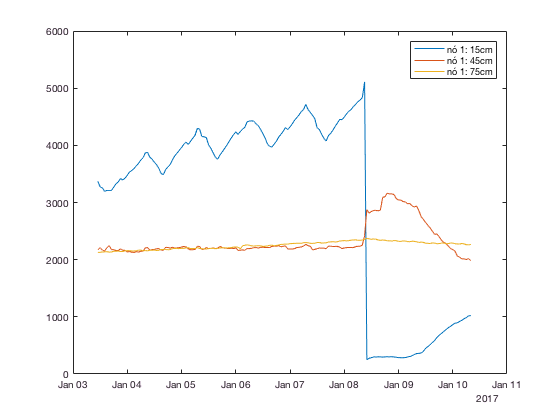

plot(wmlog_node1.time(16:181),wmlog_node1.sensor01value(16:181),'DisplayName','nó 1: 15cm')
hold on
plot(wmlog_node1.time(16:181),wmlog_node1.sensor02value(16:181),'DisplayName','nó 1: 45cm')
hold on
plot(wmlog_node1.time(16:181),wmlog_node1.sensor03value(16:181),'DisplayName','nó 1: 75cm')
% plot(wmlog_node1.time(16:181),teste.sensor03value(16:181),'DisplayName','nó 1: 75cm')
hold off
legend('show')

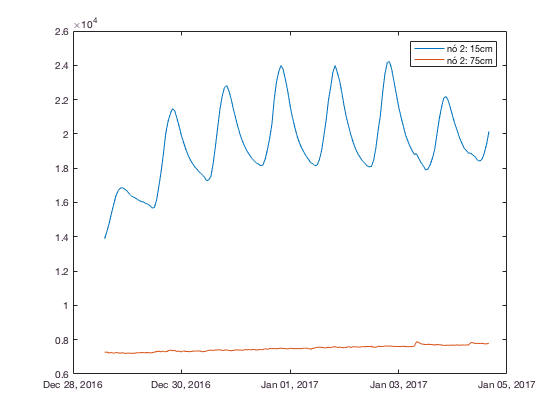

% sensor 1 (15cm) com valores muito altos
% sensor 2 (45cm) ignorado por ter maioria das leituras nulas (-1 ou -4700)
plot(wmlog_node2.time(22:193),wmlog_node2.sensor01value(22:193),'DisplayName','nó 2: 15cm')
hold on
% plot(wmlog_node2.time(22:193),wmlog_node2.sensor02value(22:193),'DisplayName','nó 2: 45cm')
% hold on
plot(wmlog_node2.time(22:193),wmlog_node2.sensor03value(22:193),'DisplayName','nó 2: 75cm')
hold off
legend('show')

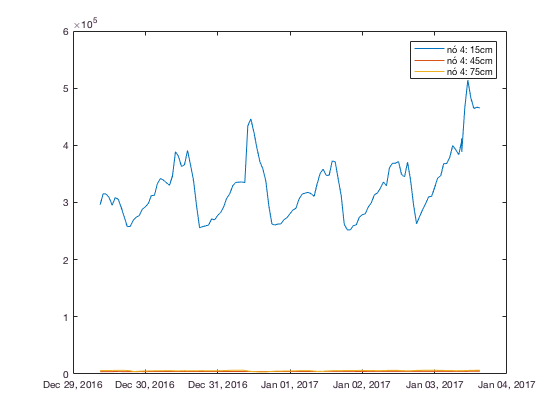

% sensor 1 (15cm) com valores muito altos
plot(wmlog_node4.time(15:end),wmlog_node4.sensor01value(15:end),'DisplayName','nó 4: 15cm')
hold on
plot(wmlog_node4.time(15:end),wmlog_node4.sensor02value(15:end),'DisplayName','nó 4: 45cm')
hold on
plot(wmlog_node4.time(15:end),wmlog_node4.sensor03value(15:end),'DisplayName','nó 4: 75cm')
hold off
legend('show')